%% SVD-Based Technique for Noise Reduction in REAL EEG Signals
% EXACT methodological match to simulation code
% Sadasivan & Dutt, Signal Processing 55 (1996)

clear; clc; close all;

%% ===================== PARAMETERS =====================

Fs = 128;
p  = 16;

base_path = 'C:\Users\mrudu\Downloads\dataset\thisone';

files = dir(fullfile(base_path,'*.md.csv'));

fprintf('\nFound %d EEG files\n',length(files));


Found 6 EEG files



================ Sub 1 - Session 1 ================


Sub 1 - Session 1 (F3 electrode)


Energy loss (1 ref AF3): 69.07 %


Energy loss (2 refs AF3+AF4): 69.14 %


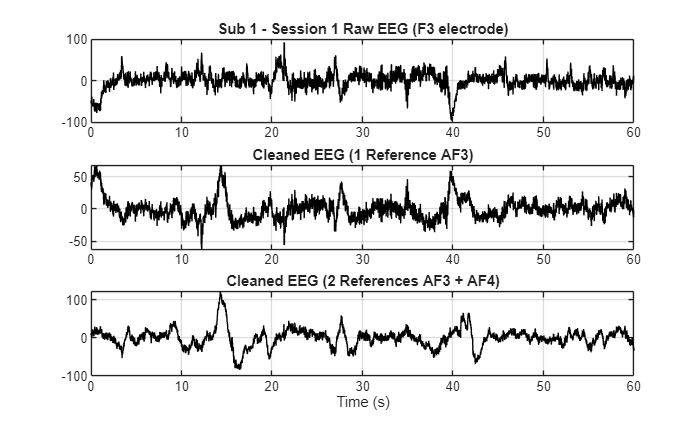

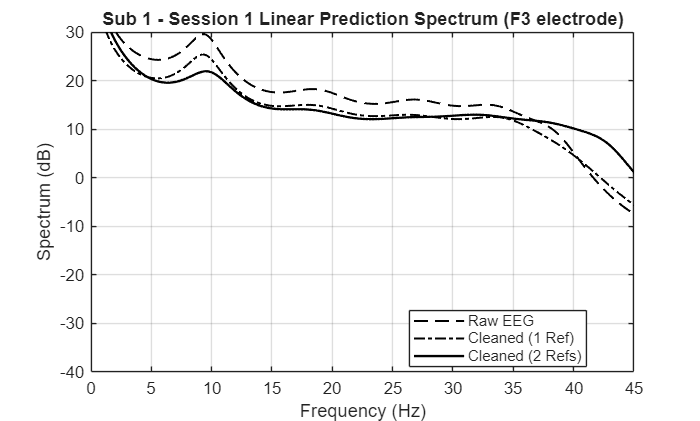

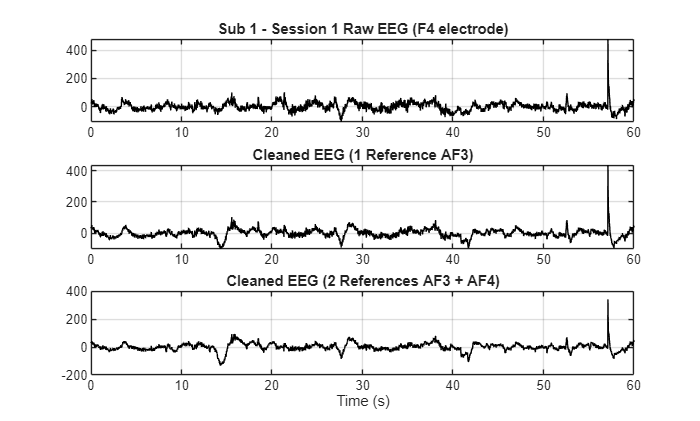

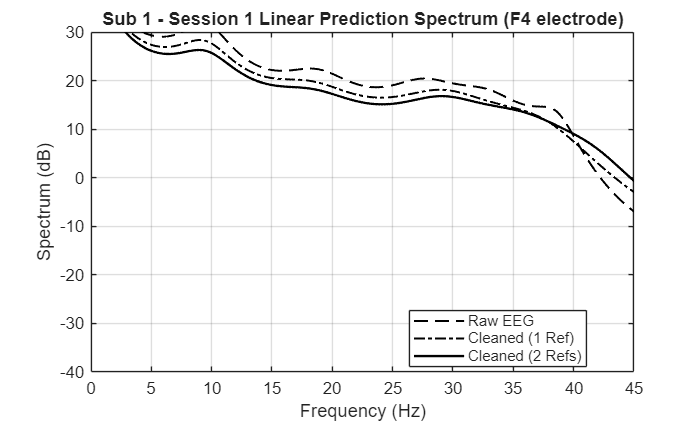


================ Sub 1 - Session 2 ================


Sub 1 - Session 2 (F3 electrode)


Energy loss (1 ref AF3): 76.73 %


Energy loss (2 refs AF3+AF4): 76.52 %


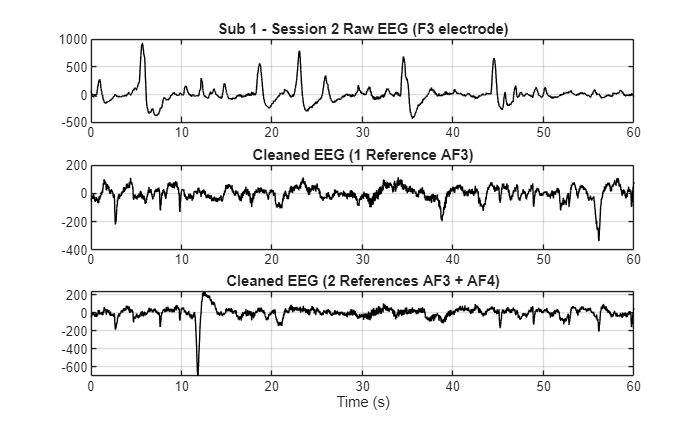

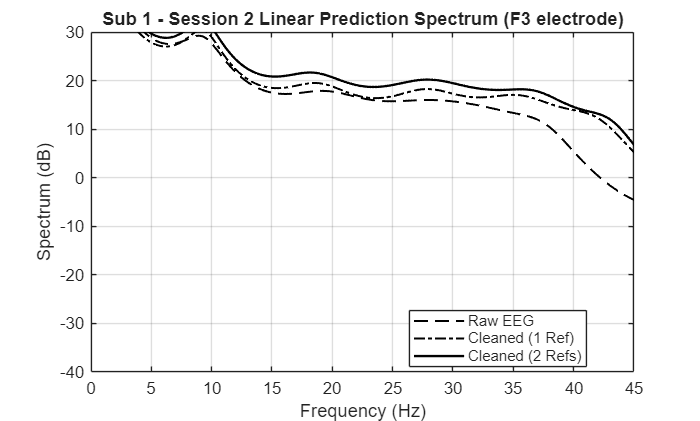

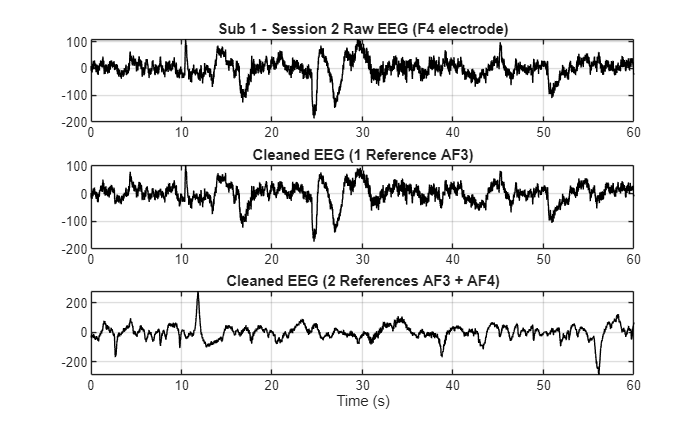

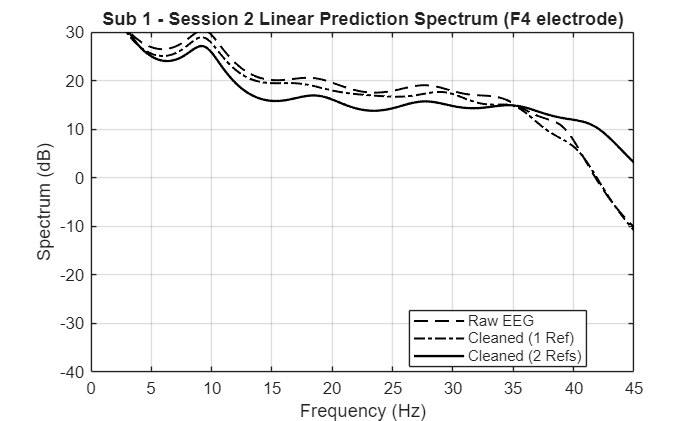


================ Sub 1 - Session 3 ================


Sub 1 - Session 3 (F3 electrode)


Energy loss (1 ref AF3): 61.06 %


Energy loss (2 refs AF3+AF4): 67.73 %


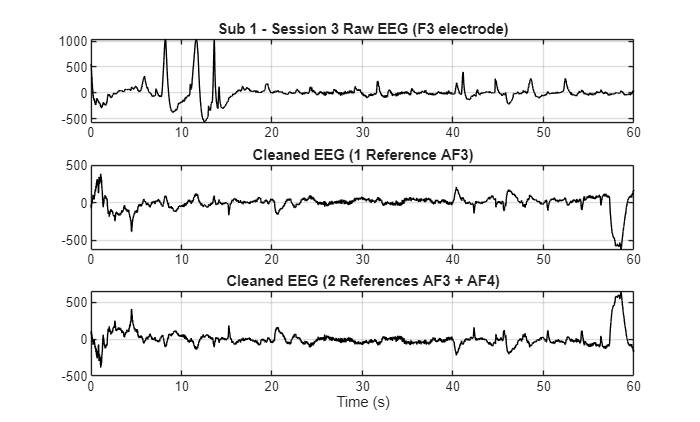

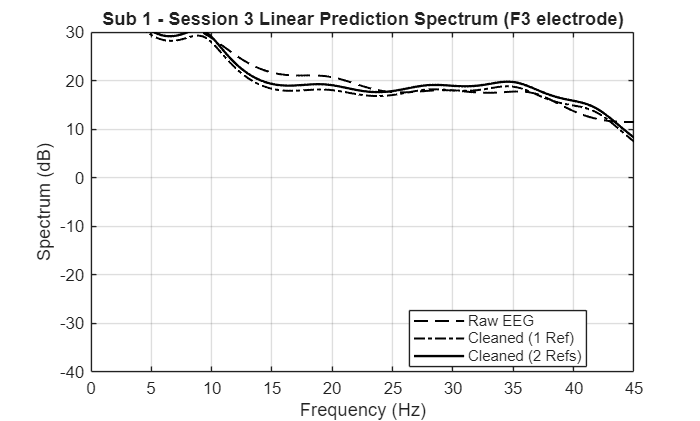

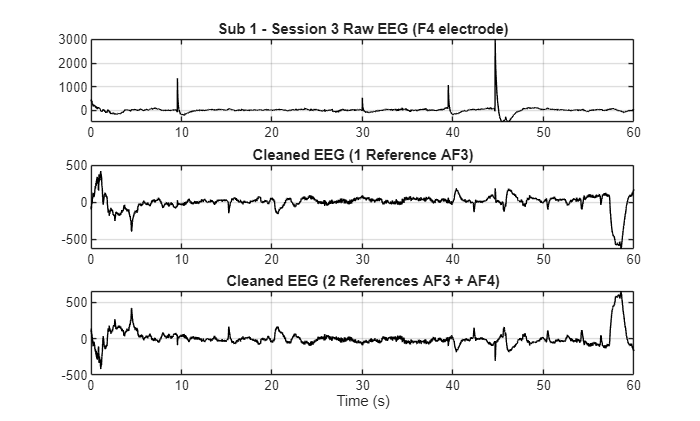

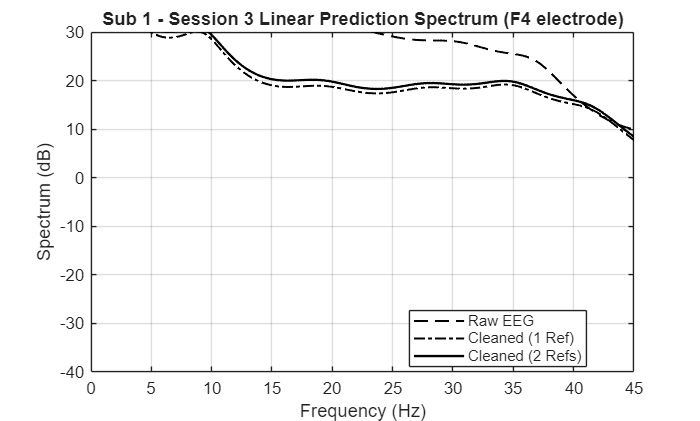


================ Sub 1 - Session 4 ================


Sub 1 - Session 4 (F3 electrode)


Energy loss (1 ref AF3): 76.18 %


Energy loss (2 refs AF3+AF4): 82.14 %


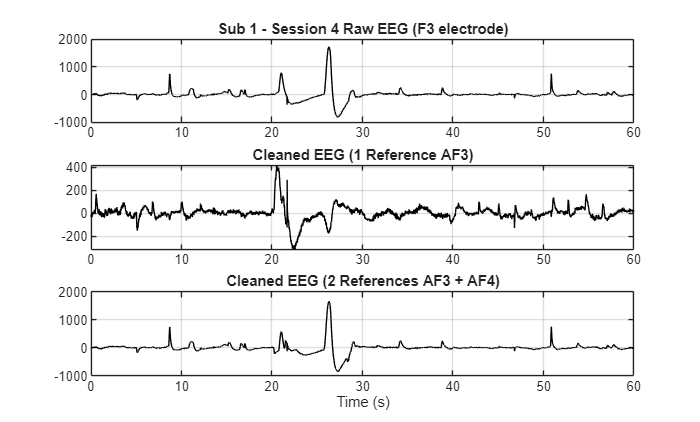

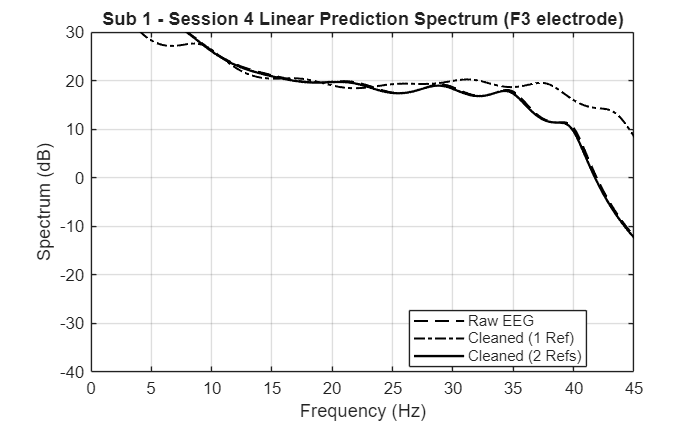

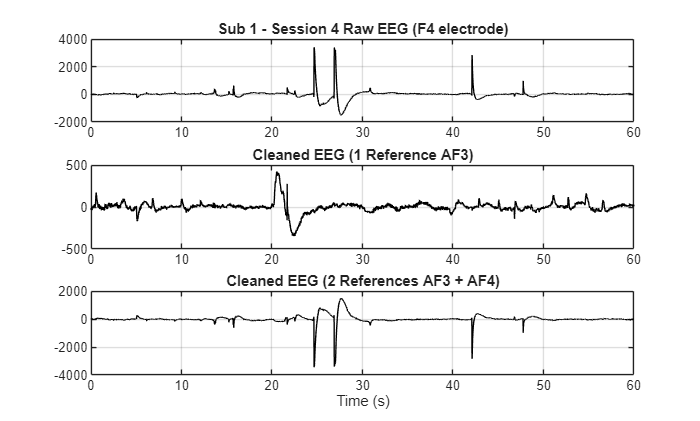

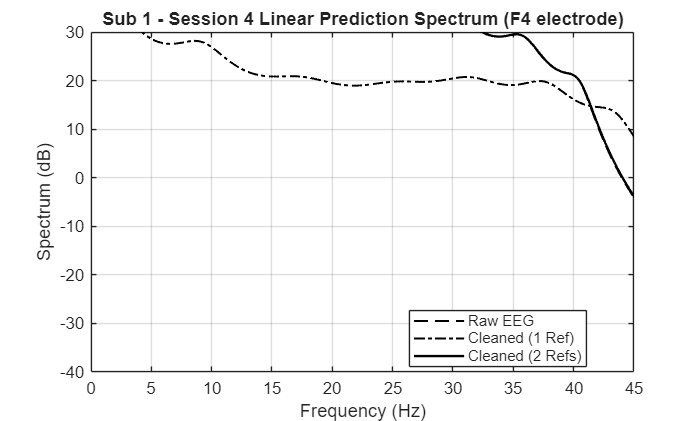


================ Sub 1 - Session 5 ================


Sub 1 - Session 5 (F3 electrode)


Energy loss (1 ref AF3): 61.84 %


Energy loss (2 refs AF3+AF4): 78.47 %


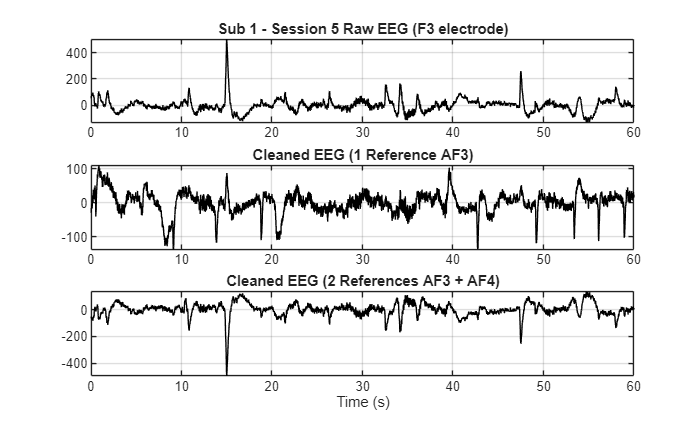

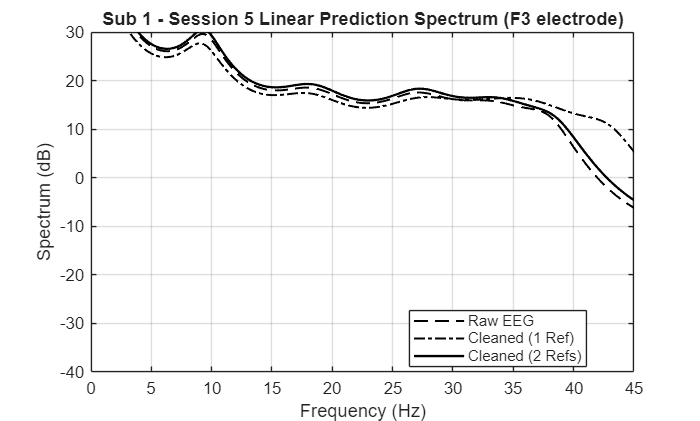

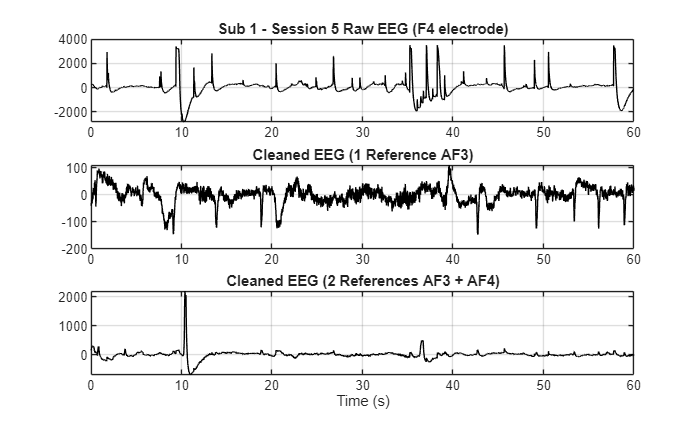

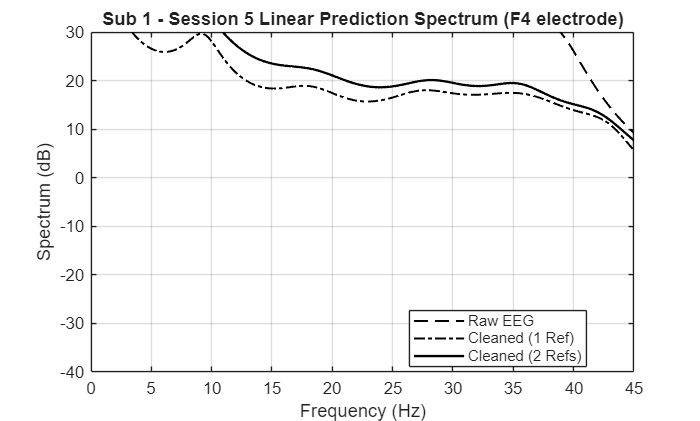


================ Sub 1 - Session 6 ================


Sub 1 - Session 6 (F3 electrode)


Energy loss (1 ref AF3): 73.10 %


Energy loss (2 refs AF3+AF4): 86.49 %


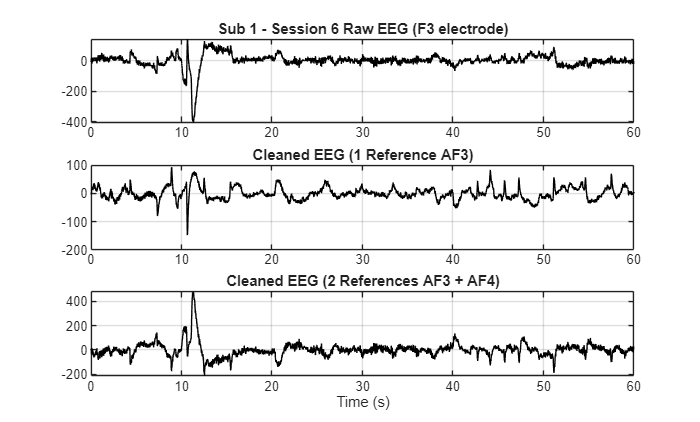

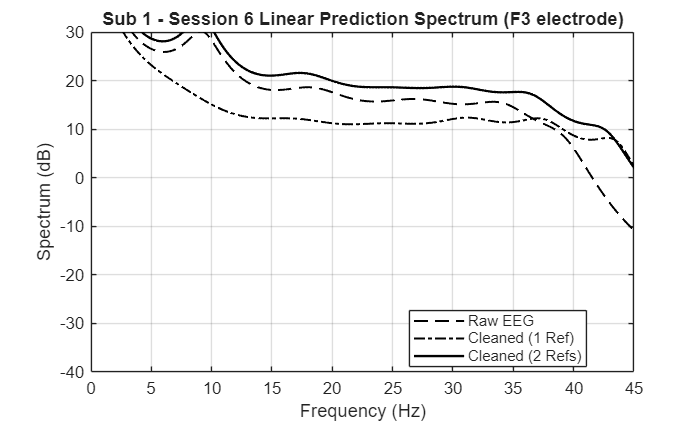

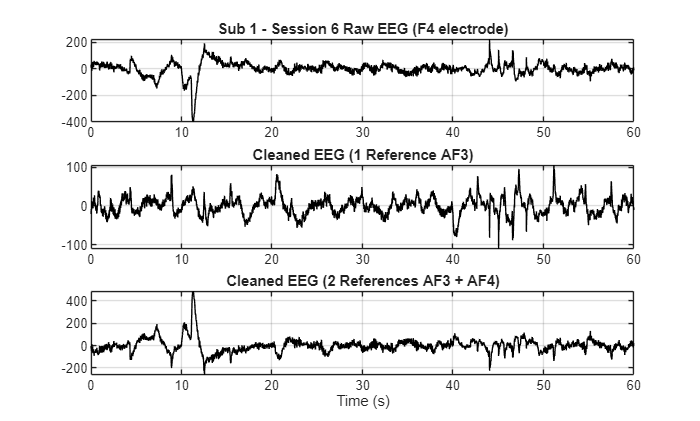

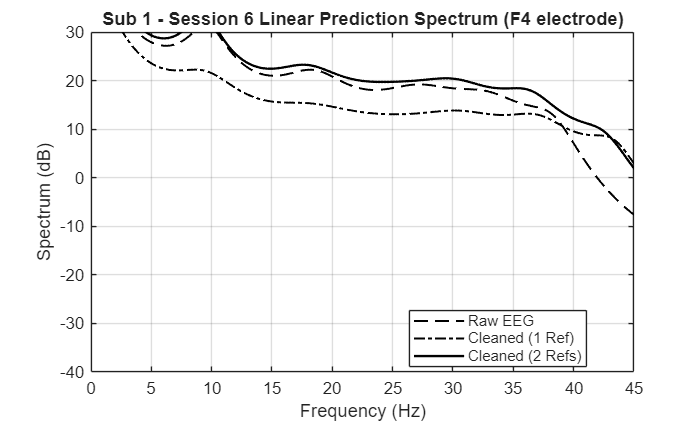


%% ===================== LOOP OVER CSV FILES =====================

for f = 1:length(files)

    file = fullfile(base_path,files(f).name);

    subject_name = sprintf('Sub 1 - Session %d',f);

    fprintf('\n================ %s ================\n',subject_name);

    %% -------- LOAD DATA --------

    T = readtable(file);

    eeg_F3   = double(T.EEG_F3)';
    eeg_F4   = double(T.EEG_F4)';
    eog_left  = double(T.EEG_AF3)';
    eog_right = double(T.EEG_AF4)';

    %% -------- KEEP ONLY FIRST 1 MINUTE --------

    N1 = 60*Fs;

    eeg_F3   = eeg_F3(1:N1);
    eeg_F4   = eeg_F4(1:N1);
    eog_left  = eog_left(1:N1);
    eog_right = eog_right(1:N1);

    t = (0:N1-1)/Fs;

    %% -------- PREPROCESSING --------

    eeg_F3   = detrend(eeg_F3 - mean(eeg_F3));
    eeg_F4   = detrend(eeg_F4 - mean(eeg_F4));
    eog_left  = detrend(eog_left - mean(eog_left));
    eog_right = detrend(eog_right - mean(eog_right));

    [b_lp,a_lp] = butter(4,40/(Fs/2),'low');

    eeg_F3 = filtfilt(b_lp,a_lp,eeg_F3);
    eeg_F4 = filtfilt(b_lp,a_lp,eeg_F4);

    %% ====================== F3 ANALYSIS ======================

    eeg_raw = eeg_F3;

    M1 = [eeg_raw; eog_left];
    M2 = [eeg_raw; eog_left; eog_right];

    [U1,S1,~] = svd(M1,'econ');
    [U2,S2,~] = svd(M2,'econ');

    S1_mat = U1' * M1;
    S2_mat = U2' * M2;

    eeg_clean_1 = S1_mat(2,:);
    eeg_clean_2 = S2_mat(2,:);

    %% ENERGY USING SECOND COMPONENT

    energy_M1_original = sum(diag(S1));
    energy_M2_original = sum(diag(S2));

    energy_M1_clean = S1(2,2);
    energy_M2_clean = S2(2,2);

    loss_1ref = (energy_M1_original - energy_M1_clean)/energy_M1_original*100;
    loss_2ref = (energy_M2_original - energy_M2_clean)/energy_M2_original*100;

    fprintf('%s (F3 electrode)\n',subject_name);
    fprintf('Energy loss (1 ref AF3): %.2f %%\n',loss_1ref);
    fprintf('Energy loss (2 refs AF3+AF4): %.2f %%\n',loss_2ref);

    %% -------- TIME DOMAIN PLOT (F3) --------

    figure('Color','w','Name',[subject_name,' - F3 Analysis'])

    subplot(3,1,1)
    plot(t,eeg_raw,'k'); grid on
    title([subject_name,' Raw EEG (F3 electrode)'])

    subplot(3,1,2)
    plot(t,eeg_clean_1,'k'); grid on
    title('Cleaned EEG (1 Reference AF3)')

    subplot(3,1,3)
    plot(t,eeg_clean_2,'k'); grid on
    title('Cleaned EEG (2 References AF3 + AF4)')
    xlabel('Time (s)')

    %% -------- LP SPECTRUM (F3) --------

    [As_raw,Es_raw] = aryule(eeg_raw,p);
    [As_1,Es_1]     = aryule(eeg_clean_1,p);
    [As_2,Es_2]     = aryule(eeg_clean_2,p);

    [H_raw,w] = freqz(sqrt(Es_raw),As_raw,512,Fs);
    H1 = freqz(sqrt(Es_1),As_1,512,Fs);
    H2 = freqz(sqrt(Es_2),As_2,512,Fs);

    figure('Color','w','Name',[subject_name,' - LP Spectrum F3'])

    plot(w,20*log10(abs(H_raw)),'k--','LineWidth',1.2); hold on
    plot(w,20*log10(abs(H1)),'k-.','LineWidth',1.2)
    plot(w,20*log10(abs(H2)),'k','LineWidth',1.4)

    grid on
    xlabel('Frequency (Hz)')
    ylabel('Spectrum (dB)')
    legend('Raw EEG','Cleaned (1 Ref)','Cleaned (2 Refs)','Location','Best')

    title([subject_name,' Linear Prediction Spectrum (F3 electrode)'])

    xlim([0 45])
    ylim([-40 30])

    %% ====================== F4 ANALYSIS ======================

    eeg_raw = eeg_F4;

    M1 = [eeg_raw; eog_left];
    M2 = [eeg_raw; eog_left; eog_right];

    [U1,S1,~] = svd(M1,'econ');
    [U2,S2,~] = svd(M2,'econ');

    S1_mat = U1' * M1;
    S2_mat = U2' * M2;

    eeg_clean_1 = S1_mat(2,:);
    eeg_clean_2 = S2_mat(2,:);

    %% -------- TIME DOMAIN PLOT (F4) --------

    figure('Color','w','Name',[subject_name,' - F4 Analysis'])

    subplot(3,1,1)
    plot(t,eeg_raw,'k'); grid on
    title([subject_name,' Raw EEG (F4 electrode)'])

    subplot(3,1,2)
    plot(t,eeg_clean_1,'k'); grid on
    title('Cleaned EEG (1 Reference AF3)')

    subplot(3,1,3)
    plot(t,eeg_clean_2,'k'); grid on
    title('Cleaned EEG (2 References AF3 + AF4)')
    xlabel('Time (s)')

    %% -------- LP SPECTRUM (F4) --------

    [As_raw,Es_raw] = aryule(eeg_raw,p);
    [As_1,Es_1]     = aryule(eeg_clean_1,p);
    [As_2,Es_2]     = aryule(eeg_clean_2,p);

    [H_raw,w] = freqz(sqrt(Es_raw),As_raw,512,Fs);
    H1 = freqz(sqrt(Es_1),As_1,512,Fs);
    H2 = freqz(sqrt(Es_2),As_2,512,Fs);

    figure('Color','w','Name',[subject_name,' - LP Spectrum F4'])

    plot(w,20*log10(abs(H_raw)),'k--','LineWidth',1.2); hold on
    plot(w,20*log10(abs(H1)),'k-.','LineWidth',1.2)
    plot(w,20*log10(abs(H2)),'k','LineWidth',1.4)

    grid on
    xlabel('Frequency (Hz)')
    ylabel('Spectrum (dB)')
    legend('Raw EEG','Cleaned (1 Ref)','Cleaned (2 Refs)','Location','Best')

    title([subject_name,' Linear Prediction Spectrum (F4 electrode)'])

    xlim([0 45])
    ylim([-40 30])

end


fprintf('\nALL CSV EEG FILES PROCESSED WITH IDENTICAL METHODS.\n');


ALL CSV EEG FILES PROCESSED WITH IDENTICAL METHODS.
